
%my_table = innerjoin(tbl,subjectids);

for i=1:size(tbl.Subject,1)
    newcol(i) = join(tbl.Subject(i), tbl.Dataset(i))
end


expid = 1;
pstruct = zeros(36,8,9);
fstruct = zeros(36,8,9);
perchangestruct = zeros(36,8,9);
coeffstruct = zeros(36,8,9);

%pstruct = zeros(36,6,5);
%fstruct = zeros(36,5,5);
%perchangestruct = zeros(36,6,5);
%coeffstruct = zeros(36,6,5);

for dataid = {"A" , "B", "C", "D", "E", "F", "G", "H", "I"}
    %tbl = readtable("Stratified_GoodSites - 3Experiments.csv")
    tbl=readtable("3Experiments_"+dataid+".csv");
    %tbl = readtable("3Experiments_wBLSA_"+dataid+".csv");
    tbl.SubjectID = categorical(tbl.SubjectID);
    %tbl.SiteID = categorical(tbl.SiteID);
    %tbl.Sex = categorical(tbl.Sex);
    %tbl.diagnosis = categorical(tbl.diagnosis);
    coeffs = table
    pvals = table
    percentchanges  = table
    fstats = table
    for colname = experimentnames
        %formula = ""+tbl.Properties.VariableNames{index} + ' ~ Age*SiteID + Sex*SiteID + diagnosis*SiteID + Sex*diagnosis + Age*diagnosis + (1|SubjectID)'
        formula = ""+colname + ' ~ SiteID*Age + SiteID*Sex + SiteID*diagnosis + (1|SubjectID)'
        %formula = ""+tbl.Properties.VariableNames{index} + ' ~ Age + Sex + diagnosis + SiteID + (1|Subject)'
        %formula = ""+colname + ' ~ Age + Sex + diagnosis + SiteID + (1|Subject)'
        
        lme = fitlme(tbl,formula);
        anovatest = anova(lme).FStat;
        %lme.CoefficientNames
        %lme.Coefficients.Estimate
        
        thiscoeff = {colname,lme.Coefficients.Estimate(1), lme.Coefficients.Estimate(2), lme.Coefficients.Estimate(3), lme.Coefficients.Estimate(4), lme.Coefficients.Estimate(5), lme.Coefficients.Estimate(6),lme.Coefficients.Estimate(7), lme.Coefficients.Estimate(8)};
        thisp = {colname,lme.Coefficients.pValue(1), lme.Coefficients.pValue(2), lme.Coefficients.pValue(3), lme.Coefficients.pValue(4), lme.Coefficients.pValue(5), lme.Coefficients.pValue(6), lme.Coefficients.pValue(7), lme.Coefficients.pValue(8)};
        thispercentchange = {colname,0*lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(2)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(3)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(4)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(5)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(6)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(7)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(8)/lme.Coefficients.Estimate(1)};
        thisf = {colname, anovatest(1), anovatest(2), anovatest(3), anovatest(4), anovatest(5), anovatest(6), anovatest(7), anovatest(8)};
        
        %thisf = {colname, anovatest(1), anovatest(2), anovatest(3), anovatest(4), anovatest(5)};
        %thiscoeff = {colname,lme.Coefficients.Estimate(end-2), lme.Coefficients.Estimate(end-1), lme.Coefficients.Estimate(end)};
        %thisp = {colname,lme.Coefficients.pValue(end-2), lme.Coefficients.pValue(end-1), lme.Coefficients.pValue(end)};
        %thispercentchange = {colname,0*lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(end-2)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(end-1)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(end)/lme.Coefficients.Estimate(1)};
        %thiscoeff = {tbl.Properties.VariableNames{index},lme.Coefficients.Estimate(1), lme.Coefficients.Estimate(2), lme.Coefficients.Estimate(3), lme.Coefficients.Estimate(4), lme.Coefficients.Estimate(5), lme.Coefficients.Estimate(6), lme.Coefficients.Estimate(7), lme.Coefficients.Estimate(8)};
        %thisp = {tbl.Properties.VariableNames{index},lme.Coefficients.pValue(1), lme.Coefficients.pValue(2), lme.Coefficients.pValue(3), lme.Coefficients.pValue(4), lme.Coefficients.pValue(5), lme.Coefficients.pValue(6), lme.Coefficients.pValue(7), lme.Coefficients.pValue(8)};
        %thispercentchange = {tbl.Properties.VariableNames{index},0*lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(2)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(3)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(4)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(5)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(6)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(7)/lme.Coefficients.Estimate(1), 100*lme.Coefficients.Estimate(8)/lme.Coefficients.Estimate(1)};
        
        coeffs = [coeffs; thiscoeff];
        pvals = [pvals; thisp];
        percentchanges = [percentchanges; thispercentchange];
        fstats = [fstats; thisf];
    end
    
    p = table2array(pvals(:,2:end));
    arr = table2array(fstats(:,2:end));
    coeffs_arr = table2array(coeffs(:,2:end));
    percentchange_arr = table2array(percentchanges(:,2:end));

    perchangestruct(:,:,expid) = percentchange_arr;
    pstruct(:,:,expid) = p;
    fstruct(:,:,expid) = arr;
    coeffstruct(:,:,expid) = coeffs_arr;
    expid = expid+1;
    disp(dataid);
    disp("Done!");
end
%lme = fitlme(tbl,'diagnosis ~ betweenness_centrality_pred + modularity_pred + assortativity_pred + participation_pred + clustering_pred + nodal_strength_pred + local_efficiency_pred + global_efficiency_pred + density_pred + rich_club_pred + path_length_pred + edge_count_pred');


p = table2array(pvals(:,2:end));
imagesc(p>0.05);
xticklabels(lme.CoefficientNames);
xticks(1:8)
yticks(1:36)
yticklabels(experimentnames)
colorbar;
colormap(sky);

sumofp = sumofp + (p<0.05)

%p = table2array(pvals(:,2:end));
%arr(p>0.05)=NaN

%arr = table2array(percentchanges(:,3:end));
imagesc(b, [0 9]);
xticks(1:7)
xticklabels(lme.CoefficientNames(2:end));
yticks(1:36);
yticklabels(experimentnames);
colorbar;

colormap(coolwarm(201));


%p = table2array(fstats(:,2:end));
%arr(p>0.05)=NaN
arr = table2array(fstats(:,3:end));
imagesc(arr);
xticks(1:7)
xticklabels(lme.CoefficientNames(2:end));
yticks(1:36);
yticklabels(experimentnames);
colorbar;
colormap(hot)
%colormap(coolwarm(201));

sumoft = sumoft + fstats(:,3:end);


thing = coeffs; %fstruct;%coeffstruct;
thing(p(:,:,:)>=0.05)=NaN;


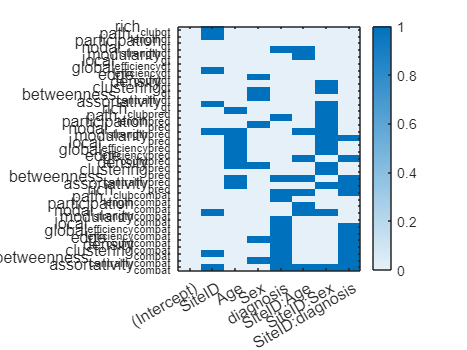

stdev_ = std(thing,0,3, "omitmissing");
mean_ = nanmean(thing, 3); 
mean_(isnan(mean_)) = 0;

%cov = stdev_(:,2:end) ./ mean_(:,2:end);
cov = stdev_ ./ mean_;
%cov=mean_(:,2:end);
figure; imagesc(100*cov,[0 100]); colorbar;% xticklabels(k.Term(2:end));
hold on;

%colormap(hot);

for measureid=1:36
    a = squeeze(coeffstruct(measureid,:,:));
    iccs_coeffs(measureid) = ICC(a,"C-1");
end

% [0.5, 0.75, 0.9, 1];
pastel_colors = [
    0.9 0.7 0.8;
    0.9 0.7 0.8;
    0.9 0.7 0.8;
    0.9 0.7 0.8;
    0.9 0.7 0.8;
    0.9 0.7 0.8;
    0.9 0.7 0.8;
    0.9 0.7 0.8;
    0.9 0.7 0.8;
    0.9 0.7 0.8;
    0.9 0.9 0.7;
    0.9 0.9 0.7;
    0.9 0.9 0.7;
    0.9 0.9 0.7;
    0.9 0.9 0.7;
    0.8 0.8 0.9;
    0.8 0.8 0.9;
    0.8 0.8 0.9;
    0.7 0.9 0.8;
    0.7 0.9 0.8;
]
nn = transpose(reshape(iccs_coeffs, [3 12]));
figure; imagesc(nn); colormap(pastel_colors); colorbar; hold on;
xticklabels({"BL","Proposed model","ComBat"});
xticks([1 2 3]);




figure;
tiledlayout("flow");
for i = 1:1
    nexttile;
    %figure;
    a = transpose(squeeze(fstruct(i,:,:)));
    b = transpose(squeeze(fstruct(i+12,:,:)));
    c = transpose(squeeze(fstruct(i+24,:,:)));
    a_boxplot = boxplot(a, 'positions',4*(1:7), 'colors', [0.2 0.1 0.1], 'Widths',0.2);
    hold on;
    b_boxplot = boxplot(b, 'positions',4*(1:7)+1, 'colors', [0.1 0.2 0.1], 'Widths',0.2);
    c_boxplot = boxplot(c, 'positions',4*(1:7)+2, 'colors', [0.1 0.1 0.], 'Widths',0.2);
    %positiclcclecons = [3*(zeros(12,1)+0.5) 3*(zeros(12,1)+1) 3*(zeros(12,1)+1.5)];
    %bc = boxplot([a b c]);
    %bc.Groups = [3*(zeros(12,1)+0.5) 3*(zeros(12,1)+1) 3*(zeros(12,1)+1.5)];
    %bc.Positions = [3*(zeros(12,1)+0.5) 3*(zeros(12,1)+1) 3*(zeros(12,1)+1.5)] 
    xticks(4*(1:7)+1);
    %xticks(2:3:21);
    xticklabels({"Site", "Age", "Sex", "Dx", "Site:Age", "Site:Sex", "Site:Dx"});
end


figure;
t=tiledlayout("flow");
coeffnames = {"Intercept","Site", "Age", "Sex", "Dx", "Site:Age", "Site:Sex", "Site:Dx"};
for i = 1:12
    figure;
    measurename = measurenames(i);
    title(t,measurename);
    for coeffid=[1 3 4 5] 
    nexttile;
    %figure;
    a = transpose(squeeze(thing(i,coeffid,:)));
    b = transpose(squeeze(thing(i+12,coeffid,:)));
    c = transpose(squeeze(thing(i+24,coeffid,:)));
    a_boxplot = boxplot(a, 'positions',1, 'colors', [0.2 0.1 0.1], 'Widths',0.2);
    hold on;
    b_boxplot = boxplot(b, 'positions',2, 'colors', [0.1 0.2 0.1], 'Widths',0.2);
    c_boxplot = boxplot(c, 'positions',3, 'colors', [0.1 0.1 0.], 'Widths',0.2);
    %positiclcclecons = [3*(zeros(12,1)+0.5) 3*(zeros(12,1)+1) 3*(zeros(12,1)+1.5)];
    %bc = boxplot([a b c]);
    %bc.Groups = [3*(zeros(12,1)+0.5) 3*(zeros(12,1)+1) 3*(zeros(12,1)+1.5)];
    %bc.Positions = [3*(zeros(12,1)+0.5) 3*(zeros(12,1)+1) 3*(zeros(12,1)+1.5)] 
    %xticks(4*(1:7)+1);
    %xticks(2:3:21);
    title(coeffnames(coeffid))
    %xticklabels({"Site", "Age", "Sex", "Dx", "Site:Age", "Site:Sex", "Site:Dx"});
    end
end


figure;
t=tiledlayout("flow");
experimentname={"GT", "Model", "ComBat"};
for measureid=4:4
    figure;
    title(measureid)
    %plot(squeeze(perchangestruct(1,:,:)));
    for expid=1:3
        nexttile;
        title(experimentname(expid));
        for i=1:8
            barchart(squeeze((coeffstruct(12*(expid-1)+measureid,i,:))));
            hold on;
            xlabel("Data Configuration");
            xticklabels({"A","B", "C", "D","E", "F", "G", "H", "I"});
            ylabel("\beta");
            ylim([-100 100]);
        end
    end

end
legend(lme.CoefficientNames(2:end));

figure;
t=tiledlayout("flow");
report_sex = table;
%tbl = readtable("Stratified_GoodSites - 3Experiments.csv")
tbl=readtable("Stratified_GoodSites - 3Experiments.csv");
tbl.SubjectID = categorical(tbl.SubjectID);
tbl.Sex = categorical(tbl.Sex);
measureid=11;
for colname = experimentnames(13:24)
    
    nexttile;
    boxchart(tbl.Sex,table2array(tbl(:,measureid)), 'GroupByColor',tbl.Sex, 'BoxFaceAlpha',0);
    a = table2array(tbl(tbl.Sex=="0",measureid));
    b = table2array(tbl(tbl.Sex=="1",measureid));
    [p,h]=ranksum(a,b);
    thisreport = {colname, p};
    report_sex = [report_sex; thisreport];
    
    %xticks([1 2]);
    xticklabels({"Female", "Male"});
    ylabel(colname);
    measureid = measureid+3;
    if measureid >36
        break;
    end
end


figure;
t=tiledlayout("flow");

report = table;

%tbl = readtable("Stratified_GoodSites - 3Experiments.csv")
%tbl=readtable("Stratified_GoodSites - 3Experiments.csv");
tbl=readtable("3Experiments_I.csv");
tbl.SubjectID = categorical(tbl.SubjectID);
tbl.diagnosis = categorical(tbl.diagnosis);
measureid=14;
for colname = experimentnames(13:24)
    
    nexttile;
    boxchart(tbl.diagnosis,table2array(tbl(:,measureid)), 'GroupByColor',tbl.diagnosis);
    a = table2array(tbl(tbl.diagnosis=="1",measureid));
    b = table2array(tbl(tbl.diagnosis=="2",measureid));
    c = table2array(tbl(tbl.diagnosis=="3",measureid));
    [p1,h]=ranksum(a,b);
    [p2,h]=ranksum(b,c);
    [p3,h]=ranksum(a,c);
    thisreport = {colname, p1, p2, p3};
    %xticks([1 2]);
    xticklabels({"Female", "Male"});
    ylabel(colname);
    measureid = measureid+2;
    report = [report; thisreport];
    if measureid >36
        break;
    end
end

% Create a linearly spaced vector of hues (from 0 to 1)
n_colors = 80;
hues = linspace(0, 1, n_colors);

% Initialize the colormap
colormap_data = zeros(n_colors, 3);

% Generate RGB values from HSV (Hue, Saturation, Value)
for i = 1:n_colors
    sat = mod(i,2)/2;
    colormap_data(i, :) = hsv2rgb([hues(i), 1, 1]);
end

% Apply the custom colormap
colormap(colormap_data);
colormap_data = colormap_data(1:2:80,:);


colormap_data(1,:)=[0.5 0.5 0.5]

figure;
t=tiledlayout("flow");
report_sex = table;
tbl=readtable("3Experiments_wBLSA.csv");
%tbl = readtable("Stratified_GoodSites - 3Experiments.csv")
%tbl=readtable("Stratified_GoodSites - 3Experiments.csv");

tbl.SubjectID = categorical(tbl.Datase_subject);
tbl.Sex = categorical(tbl.Sex);
measureid=10;
for colname = experimentnames(13:24)
    
    nexttile;
    for site=1:38
        %swarmchart(tbl,'Sex',colname,'ColorVariable','SiteID');
        a = table2array(tbl(tbl.Sex=="0" & tbl.SiteID==site,measureid));
        b = table2array(tbl(tbl.Sex=="1" & tbl.SiteID==site,measureid));
        x_a = tbl.SiteID(tbl.Sex=="0" & tbl.SiteID==site);
        x_b = tbl.SiteID(tbl.Sex=="1" & tbl.SiteID==site) + 50;
        x_c = colormap_data(site,:);
        swarmchart(x_a, a, 'filled' ,  'MarkerFaceColor', x_c, 'MarkerFaceAlpha',0.1); hold on;
        swarmchart(x_b, b,  'filled' ,'MarkerFaceColor', x_c, 'MarkerFaceAlpha',0.1);
    end
    %boxchart(tbl.Sex,table2array(tbl(:,measureid)), 'GroupByColor',tbl.Sex, 'BoxFaceAlpha',0);
    a = table2array(tbl(tbl.Sex=="0",measureid));
    b = table2array(tbl(tbl.Sex=="1",measureid));
    boxchart([18.5*ones(size(a)); 68.5*ones(size(b))], [a; b], 'MarkerStyle', 'none', 'BoxWidth', 40, 'BoxFaceAlpha', 0, 'BoxEdgeColor',[0 0 0]);

    [p,h]=ranksum(a,b);
    thisreport = {colname, p};
    report_sex = [report_sex; thisreport];
    xlim([-5 92])
    xticks([18.5 68.5]);
    xticklabels({"Female", "Male"});
    ylabel(colname);
    measureid = measureid+2;
    if measureid >36
        break;
    end
end


figure;
t=tiledlayout("flow");
report = table;
%tbl = readtable("Stratified_GoodSites - 3Experiments.csv")
tbl=readtable("3Experiments_wBLSA.csv");
tbl.SubjectID = categorical(tbl.Datase_subject);
tbl.diagnosis = categorical(tbl.diagnosis);
measureid=35;
for colname = experimentnames(10:2:33)
    
    nexttile;
    for site=1:38
        %swarmchart(tbl,'Sex',colname,'ColorVariable','SiteID');
        a = table2array(tbl(tbl.diagnosis=="0" & tbl.SiteID==site,measureid));
        b = table2array(tbl(tbl.diagnosis=="0.5" & tbl.SiteID==site,measureid));
        c = table2array(tbl(tbl.diagnosis=="1" & tbl.SiteID==site,measureid));

        x_a = tbl.SiteID(tbl.diagnosis=="0" & tbl.SiteID==site);
        x_b = tbl.SiteID(tbl.diagnosis=="0.5" & tbl.SiteID==site) + 50;
        x_c = tbl.SiteID(tbl.diagnosis=="1" & tbl.SiteID==site) + 100;


        x_col = colormap_data(site,:);
        swarmchart(x_a, a, 'filled' ,  'MarkerFaceColor', x_col, 'MarkerFaceAlpha',0.1); hold on;
        swarmchart(x_b, b,  'filled' ,'MarkerFaceColor', x_col, 'MarkerFaceAlpha',0.1);
        swarmchart(x_c, c,  'filled' ,'MarkerFaceColor', x_col, 'MarkerFaceAlpha',0.1);

    end
    %boxchart(tbl.Sex,table2array(tbl(:,measureid)), 'GroupByColor',tbl.Sex, 'BoxFaceAlpha',0);
    a = table2array(tbl(tbl.diagnosis=="0",measureid));
    b = table2array(tbl(tbl.diagnosis=="0.5",measureid));
    c = table2array(tbl(tbl.diagnosis=="1",measureid));
    boxchart([18.5*ones(size(a)); 68.5*ones(size(b)); 118.5*ones(size(c))], [a; b;c], 'MarkerStyle', 'none', 'BoxWidth', 45, 'BoxFaceAlpha', 0, 'BoxEdgeColor',[0 0 0]);

    [p1,h]=ranksum(a,b);
    [p2,h]=ranksum(b,c);
    [p3,h]=ranksum(a,c);
    thisreport = {colname, p1,p2,p3};
    report = [report; thisreport];
    xlim([-5 142])
    xticks([18.5 68.5 118.5]);
    xticklabels({"Control", "MCI", "AD"});
    ylabel(colname);
    measureid = measureid+1;

    if measureid >=47
        break;
    end
end

b=reorderarr(a);

figure;
sigps = (pstruct(:,2:end,:)<=0.05)% & (coeffstruct(:,2:end,:)<0);
colorbar;
sigps = sum(sigps, 3);
clim([0 5])
imagesc(sigps)
colormap(coolwarm)

%figure; imagesc(table2array(fstats(:,3:end)),[0 10]); colorbar %; xticklabels(k.Term(2:end))
figure;
t=tiledlayout('flow');
for i=1:9
    nexttile;
    %imagesc(fstruct(:,:,i)); xticklabels({'Site','Age', 'Sex', 'Dx','site:age','site:sex', 'site:diagnosis'}); xticks(1:8); colorbar; clim([0 100])
    imagesc(pstruct(:,:,i)<0.05); xticklabels({'Site','Age', 'Sex', 'Dx','site:age','site:sex', 'site:diagnosis'}); xticks(1:8); colorbar; clim([0 1])

end



figure;
imagesc(sum(pstruct<0.05,3));
colorbar;
clim([0 10])

function outarr=reorderarr(inarr)
    outarr = zeros(size(inarr));
    outarr(1:12,:) = inarr(1:3:36,:); % controls
    outarr(13:24,:) = inarr(2:3:36,:); % pred
    outarr(25:36,:) = inarr(3:3:36,:); % combat

end

